subplot指令例子，李萨茹图

t=0:0.001:4*pi;
subplot(2,2,1);
x=sin(t);y=cos(t);
plot(x,y)

subplot(2,2,2);
x=sin(t);y=cos(3*t);
plot(x,y);

subplot(2,2,3);
x=sin(2*t);y=cos(7*t);
plot(x,y);

subplot(2,2,4);
x=sin(3*sqrt(2)*t);y=cos(3*sqrt(3)*t);
plot(x,y);

ezplot例子

ezplot('x^2+y^2=1',[-1.2,1.2]); %用隐函数画圆,-1.2<x<1.2

ezplot('sin(t)','cos(t)',[0,2*pi]); %用参数函数画圆， 默认0<t<2*pi

ezplot('tan(x/2)');  %对不连续函数会自动调整取值

patch指令左图，填充颜色效果

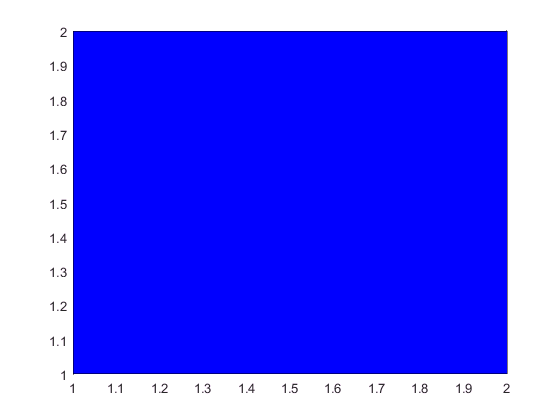

xy=[1,1;1,2;2,2];
patch('vertices',xy,'facecolor','b');

ploar作极坐标图，画心形线

t=0:0.1:2*pi;
r=(1+cos(t));
polar(t,r)

fplot作图，自带自适应功能

fplot(@(x)sin(1./x),[0.01,0.1]);
syms x;
ezplot(sin(1/x),[0.01,0.1]);%ezplot不会自适应函数(取点加密)，所以接近0处失真

复数作图

plot(Z1,Z2)=plot(real(Z1),real(Z2))

plot(Z)=plot(real(Z),imag(Z))

the=linspace(0,2*pi,100);
X=2*cos(the);Y=sin(the);
C=X+1i*Y;
plot(C);
axis equal;%坐标轴按比例显示
hold on;

C1=C*exp(1i*pi/3);
plot(C1);

C2=C1+(3-2i);
plot(C2);